%% Read data
clear, clc, close ALL

[file,path,indx] = uigetfile('*.bag', 'Select a File', '/media/minliu/dataset/MVSEC'); %gets directory
fullname = fullfile(path, file);
if isequal(file,0)
   disp('User selected Cancel')
else
   disp(['User selected ', fullname])
end

User selected /media/minliu/dataset/MVSEC/indoor_flying1_data_and_gt.bag



bag = rosbag(fullname);

% Supported on R2018a, not work on R2016b
bagInfo = rosbag('info', fullname)

bagInfo = struct with fields:
        Path: '/media/minliu/dataset/MVSEC/indoor_flying1_data_and_gt.bag'
     Version: '2.0'
    Duration: 70.3507
       Start: [1×1 struct]
         End: [1×1 struct]
        Size: 4052087535
    Messages: 173230
       Types: [6×1 struct]
      Topics: [17×1 struct]



left_pose = select(bag,'Time',...
    [bag.StartTime bag.EndTime],'Topic','/davis/left/pose')

left_pose =   BagSelection with properties:

           FilePath: '/media/minliu/dataset/MVSEC/indoor_flying1_data_and_gt.bag'
          StartTime: 1.5046e+09
            EndTime: 1.5046e+09
        NumMessages: 5695
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [5695×4 table]



msgStructs = readMessages(left_pose,'DataFormat','struct');
msgStructs{1}.Header.Stamp.Sec

ans = uint32
1504645177

length = 0.1000

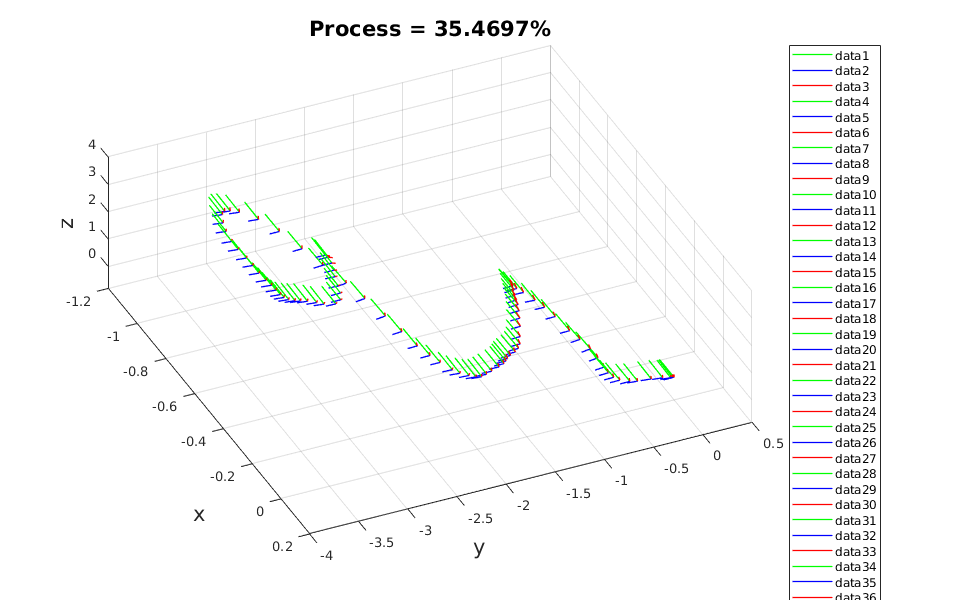


%% Extract all poses
Positions = cellfun(@(m) m.Pose.Position, msgStructs);
Orientations = cellfun(@(m) m.Pose.Orientation, msgStructs);

%% Plot poses
pose_plot(left_pose.NumMessages, Positions, Orientations);